# PHY 329 Homework 6

## Ryan Schlimme (eid: rjs4499)

# Problem 24.1

Solve the BVP for a 10 m rod with T(x=0) = 240, T(x=10) = 150 which follows the ODE: T''-0.15T=0.

## Part b) Shooting method

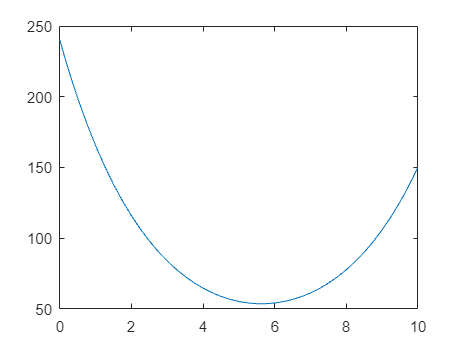

shooting_method(@ode_func1, 0, 10, 240, 150, 5, 20, 0.00001, 200)

## Part c) Finite Differences (dx = 1)

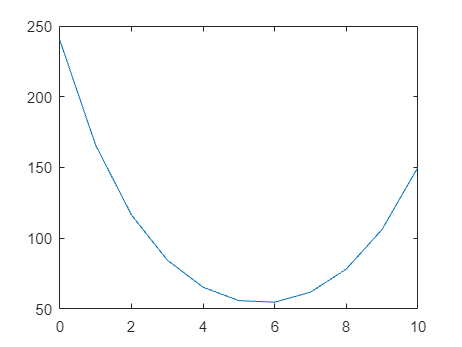

t = 0:1:10;

b = zeros(9, 1);
b(1) = -240;
b(9) = -150;

N = 9;
A = diag(-2.15*ones(1,N)) + diag(1*ones(1,N-1),1) + diag(1*ones(1,N-1),-1);

y = A\b;

y = [240;
    y(1:9);
    150];

plot(t,y)

# Problem 24.3

Solve the ODE 7y''-2y'-y+x=0, y(0)=5, y(20) = 8 using shooting method

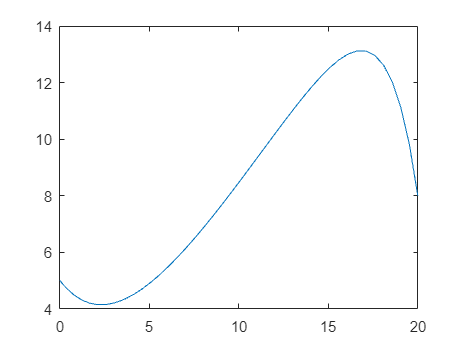

shooting_method(@ode_func3, 0, 20, 5, 8, -5, -20, 0.00001, 200)

# Problem 24.21

Solve the ODE x''+c/m*x'-g=0, x(0)=0, x(12)=500 using shooting method

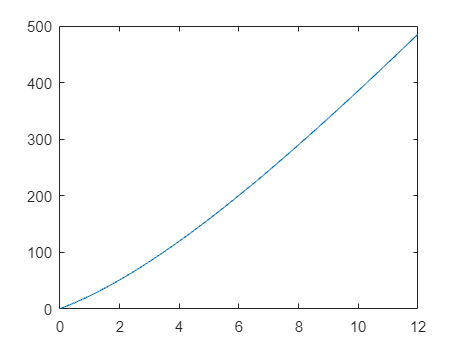

shooting_method(@ode_func21, 0, 12, 0, 500, 5, 20, 0.00001, 200)

# Problem 24.28

Solve the ODE T''=-f(x) using f(x) = 25, T(0)=40, T(10)=200.

## Part a) Shooting method

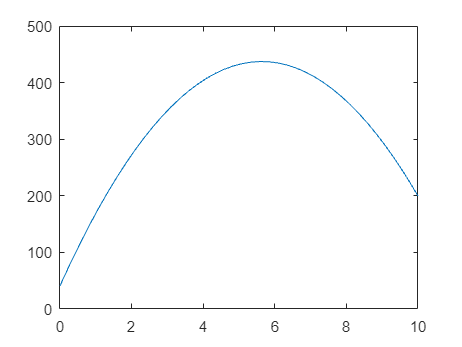

shooting_method(@ode_func28, 0, 10, 40, 200, -5, -20, 0.01, 200)

## Part b) Finite-Difference Method

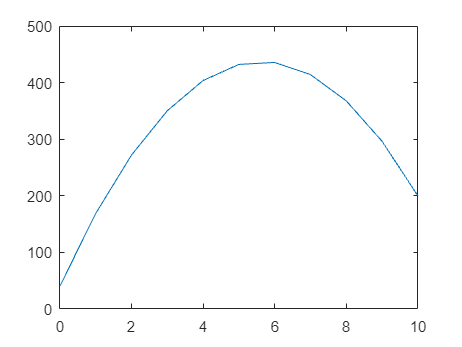

t = 0:1:10;

b = -25*ones(9, 1);
b(1) = -25-40;
b(9) = -25-200;

N = 9;
A = diag(-2*ones(1,N)) + diag(1*ones(1,N-1),1) + diag(1*ones(1,N-1),-1);

y = A\b;

y = [40;
    y(1:9);
    200];

plot(t,y)

## Part c) bvp4c

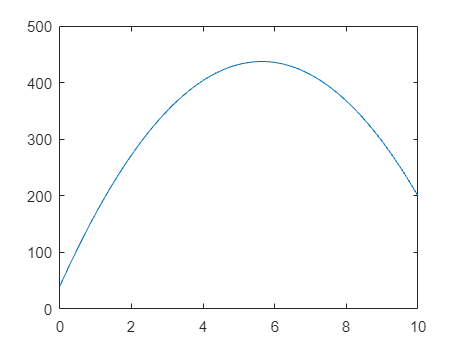

init = bvpinit(linspace(0,10,100),[1,-1]);
sol = bvp4c(@bvpfcn28, @bcfcn28, init);
x = linspace(0,10,100);
y = deval(sol, x);
plot(x,y(1,:))

# Define Our Functions

% Shooting Method

function shooting_method(ode_func, a, b, y0, yf_desired, lambda_guess1, lambda_guess2, tol, max_iter)
    error = 1;
    iter = 1;
    while error > tol && iter <= max_iter
        [t, y] = ode45(ode_func, [a b], [y0 lambda_guess1]);
        yf = y(length(y));
        [t2, y2] = ode45(ode_func, [a b], [y0 lambda_guess2]);
        yf2 = y2(length(y2));
        error = abs(yf - yf_desired);
        lambda_guess1 = lambda_guess1 + (lambda_guess2 - lambda_guess1) / (yf2+yf)*(yf_desired-yf);
        iter = iter + 1;
    end
    plot(t, y(:, 1));
end

function dydt = ode_func1(t, y)
    % Define the ODE system
    dydt = [y(2); 0.15*y(1)];
end

function dydt = ode_func3(t, y)
    % Define the ODE system
    dydt = zeros(2, 1);
    dydt(1) = y(2);
    dydt(2) = (2*y(2)+y(1)-t)/7;
end

function dydt = ode_func21(t, y)
    % Define the ODE system
    dydt = zeros(2, 1);
    dydt(1) = y(2);
    dydt(2) = 9.81 -12.5/70*y(2);
end

function dydt = ode_func28(t, y)
    % Define the ODE system
    dydt = zeros(2, 1);
    dydt(1) = y(2);
    dydt(2) = -25;
end


% 24.28 Functions
function dydx = bvpfcn28(x,y)
dydx = zeros(2,1);
dydx = [y(2);
       -25];
end

function res = bcfcn28(ya,yb)
res = [ya(1)-40
       yb(1)-200];
end